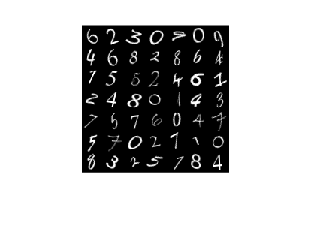

% Load Data
load DigitsDataTrain
load DigitsDataTest
numObservations = size(XTrain,4);
idx = randperm(numObservations,49);
I = imtile(XTrain(:,:,:,idx));
figure
imshow(I);

[idxTrain,idxValidation] = trainingPartitions(numObservations,[0.85 0.15]);

XValidation = XTrain(:,:,:,idxValidation);
anglesValidaiton = anglesTrain(idxValidation);

XTrain = XTrain(:,:,:,idxTrain);
anglesTrain = anglesTrain(idxTrain);

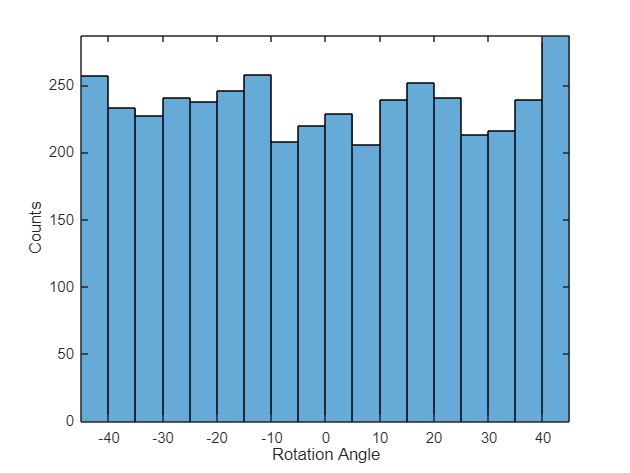

% Check Data Normalization
figure
histogram(anglesTrain)
axis tight
ylabel("Counts")
xlabel("Rotation Angle")

% Neural Network Architecture
numResponses = 1;

layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3,8,Padding="same")
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,Stride=2)
    convolution2dLayer(3,16,Padding="same")
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,Stride=2)
    convolution2dLayer(3,32,Padding="same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,32,Padding="same")
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numResponses)];

miniBatchSize  = 128;
validationFrequency = floor(numel(anglesTrain)/miniBatchSize);

options = trainingOptions("sgdm", ...
    MiniBatchSize=miniBatchSize, ...
    InitialLearnRate=1e-3, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=20, ...
    Shuffle="every-epoch", ...
    ValidationData={XTest,anglesTest}, ...
    ValidationFrequency=validationFrequency, ...
    Plots="training-progress", ...
    Metrics="rmse", ...
    Verbose=false);

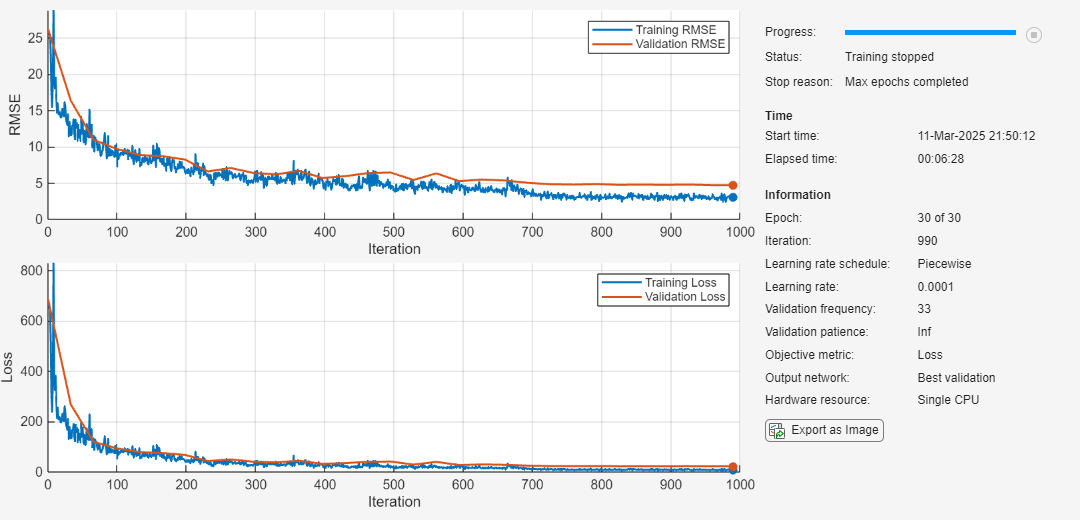

% Train Neural Network
net = trainnet(XTrain,anglesTrain,layers,"mse",options);

% Test Network
YTest = minibatchpredict(net,XTest);
predictionError = anglesTest - YTest;
squares = predictionError.^2;
rmse = sqrt(mean(squares))

rmse = single
4.7081

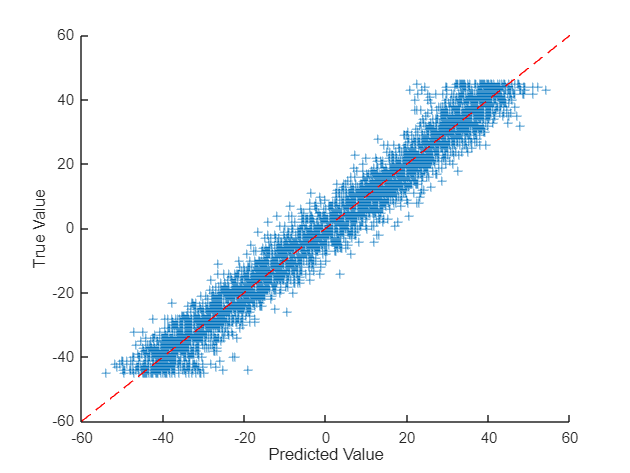

figure
scatter(YTest,anglesTest,"+")
xlabel("Predicted Value")
ylabel("True Value")

hold on
plot([-60 60], [-60 60],"r--")